%clear 
%clc

task1.1

%loading data
[audio,fs] = audioread('twomicrophones1.wav');
N=length(audio);
tp = (0:N-1)/fs;

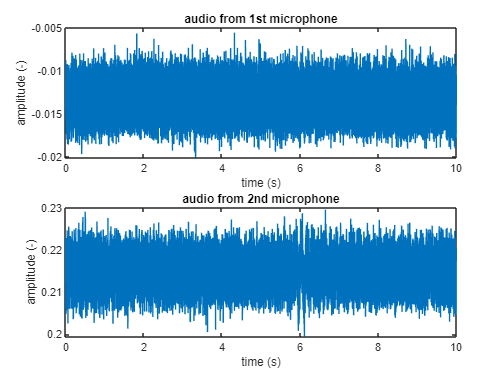

%plotting results
figure()
subplot(2,1,1)
plot(tp,audio(:,1)')
xlabel('time (s)')
ylabel('amplitude (-)')
title('audio from 1st microphone')
subplot(2,1,2)
plot(tp,audio(:,2)')
xlabel('time (s)')
ylabel('amplitude (-)')
title('audio from 2nd microphone')

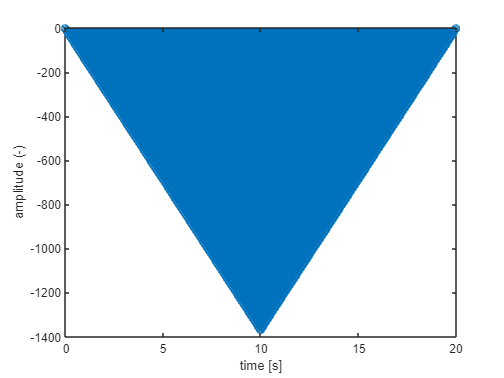

%correlation w/o compensation
[c,lags] = xcorr(audio(:,1)',audio(:,2)');
t = (0:length(lags)-1) / fs;
figure()
stem(t,c)
xlabel('time [s]') %change to seconds
ylabel('amplitude (-)')

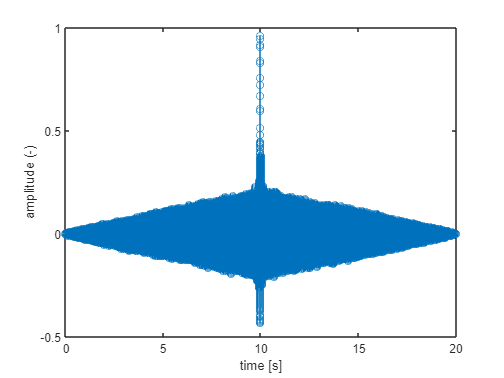

%correlation with compensation
ycomp1 = audio(:,1)'-mean(audio(:,1)');
ycomp2 = audio(:,2)'-mean(audio(:,2)');
[c2,lags2] = xcorr(ycomp1,ycomp2);

figure()
stem(t,c2)
xlabel('time [s]') %change to seconds
ylabel('amplitude (-)')

%finding time lag 
[corr_max,pos]=max(c2);
timedelay=lags2(pos)/fs;
v=345; %m/s
distance_between=abs(timedelay*v)*100 %result in cm

distance_between = 87.6875

part 2, doing the same for 2nd audiofile

%loading data
[audio,fs] = audioread('twomicrophones2.wav');
N=length(audio);
tp = (0:N-1)/fs;

%correlation with compensation
ycomp1 = audio(:,1)'-mean(audio(:,1)');
ycomp2 = audio(:,2)'-mean(audio(:,2)');
[c2,lags2] = xcorr(ycomp1,ycomp2);

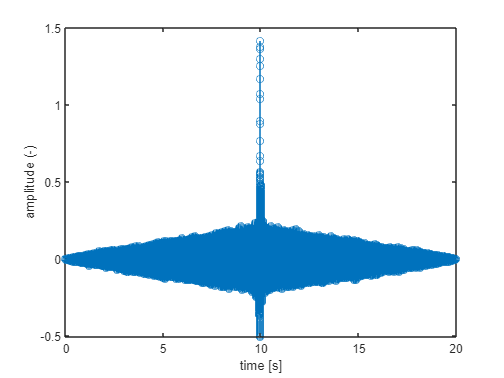

figure()
stem(t,c2)
xlabel('time [s]') %change to seconds
ylabel('amplitude (-)')

%finding time lag 
[corr_max,pos]=max(c2);
timedelay=lags2(pos)/fs;
v=345; %m/s
distance_between=abs(timedelay*v)*100 %result in cm

distance_between = 116.4375

Task1.2

%clear 
%clc

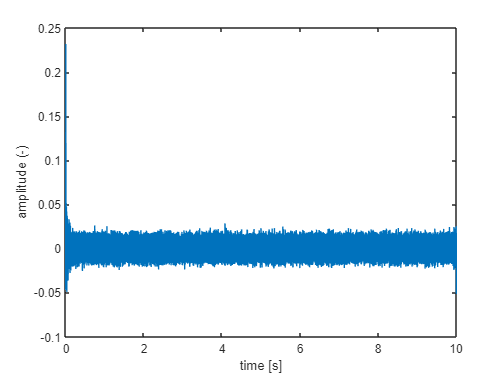

%loading data
[audio,fs] = audioread('twomicrophones1.wav');
N=length(audio);
tp = (0:N-1)/fs;
xt=audio(:,1)';
yt=audio(:,2)';
%compensating by removing constant components
xtcomp = xt-mean(xt);
ytcomp = yt-mean(yt);
%calculating spectral transmittance
Hw=fft(ytcomp)./fft(xtcomp);
%taking inverse fourier of H
ht=ifft(Hw);
%plotting the time series 
figure()
plot(tp,ht)
xlabel('time [s]') 
ylabel('amplitude (-)')

[val,loc]=max(abs(ht));
%timedelay in ms
timedelay=loc/fs

timedelay = 0.0025

%distance between microphones in cm
v=345; %m/s
distance_between=abs(timedelay*v)*100 %result in cm

distance_between = 87.6875

Task2.1

%clear
%clc

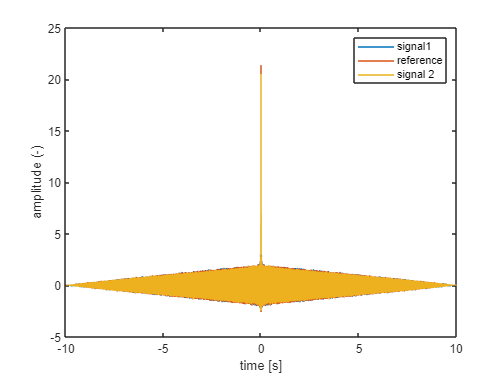

%loading the data
[audio_ref,fs] = audioread('twospeakers1_ref.wav');
[audio1,fs] = audioread('twospeakers1.wav');
[audio2,fs] = audioread('twospeakers2.wav'); %we are overwritting fs cuz its the same for all 3
%compensating
ycomp_ref = audio_ref-mean(audio_ref);
ycomp_1 = audio1-mean(audio1);
ycomp_2 = audio2-mean(audio2);
%autocorrelating ycomp_1
[c,lags] = xcorr(ycomp_1,ycomp_1);
[c2,lags2] = xcorr(ycomp_ref,ycomp_ref);
[c3,lags3] = xcorr(ycomp_2,ycomp_2);
%time vector
t = lags/ fs;
%plotting
figure()
plot(t,c), hold on
plot(t,c2)
plot(t,c3)
xlabel('time [s]') %change to seconds
ylabel('amplitude (-)')
legend('signal1','reference', 'signal 2')

%extract peak values
[val1, loc1]=max(abs(c))

val1 = 20.4668

loc1 = 480000

[val2, loc2]=max(abs(c(10*fs+1:10.0025*fs)))

val2 = 17.7204

loc2 = 1

%velocity
v=345;
%distance in signal 1
timedelay=loc1/fs-10.002548

timedelay = -0.0025

distance_between=abs(timedelay*v)*100

distance_between = 87.9060

%distance in signal 2
timedelay2=loc1/fs-10.0044375

timedelay2 = -0.0044

distance_between2=abs(timedelay2*v)*100

distance_between2 = 153.0937

Task2.2

%clear
%clc

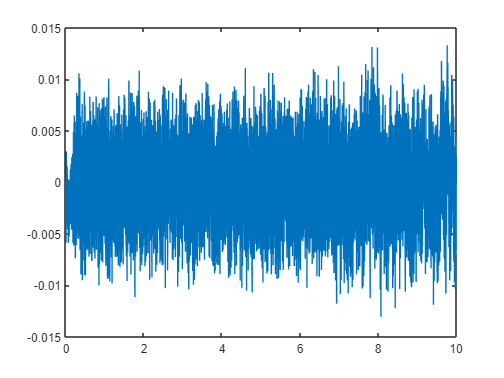

%loading the data
[audio_ref,fs] = audioread('twospeakers1_ref.wav');
[audio1,fs] = audioread('twospeakers1.wav');
[audio2,fs] = audioread('twospeakers2.wav'); %we are overwritting fs cuz its the same for all 3

%compensating
ycomp_ref = audio_ref-mean(audio_ref);
ycomp_1 = audio1-mean(audio1);
ycomp_2 = audio2-mean(audio2);

%filtering the 1st signal with filter fstop = 1000
yf=filter(Hd1,squeeze(ycomp_1));

%filtering the 1st signal with filter fstop = 300
yf2=filter(Hd2,squeeze(ycomp_2));

%time vector for plotting
N=length(audio2);
tp = (0:N-1)/fs;

%plotting
figure()
plot(tp,yf)

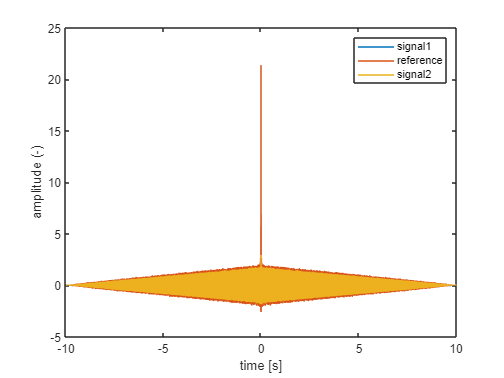


%autocorrelating
[c,lags] = xcorr(yf,yf);
[c2,lags2] = xcorr(ycomp_ref,ycomp_ref);
[c3,lags3] = xcorr(yf2,yf2);

%time vector for cr
t = lags/ fs;

%plotting
figure()
plot(t,c), hold on
plot(t,c2)
plot(t,c3)
xlabel('time [s]') %change to seconds
ylabel('amplitude (-)')
legend('signal1','reference', 'signal2')


%finding the maximum
[val1, loc1]=max(abs(c))

val1 = 5.2701

loc1 = 480000

[val2, loc2]=max(abs(c3))

val2 = 2.9244

loc2 = 480000


%velocity
v=345;
%distance in signal 1
timedelay=loc1/fs-10.00260417

timedelay = -0.0026

distance_between=abs(timedelay*v)*100

distance_between = 89.8439

%distance in signal 2
timedelay2=loc2/fs-10.00447917

timedelay2 = -0.0045

distance_between2=abs(timedelay2*v)*100

distance_between2 = 154.5314